# Getting started with the GUM toolbox

## What is GUM?

GUM is a versatile Matlab toolbox for standard and nonlinear regressions. The regression models that can be defined include standard Generalized Linear Models (GLMs), Generalized Additive Models (GAMs) and many more nonlinear regression models that belong to the larger category of Generalized Unrestricted Models (GUMs). The tutorial below is intented to show what these models are and display a glimpse of what they can be useful for when analyzing behavioral data, neural data - or just any type of data.  

The toolbox uses object-oriented programmation and R-style formulas, which allow to conveniently define a model, fit it to data and plot/display the results (and tons of other options) in a handful of lines.

## Installation

- Download/clone the toolbox.

- Add folder and subfolders to Matlab path: in the command line, write something like` addpath(genpath(FolderWhereYouPlacedThePackage));`

- .....

- Enjoy!

## **A (not-so) short tutorial: **

This tutorial presents an overview of the key features of the GUM toolbox. Explore other tutorials for a more in-depth coverage of the toolbox.

In this tutorial we will use a dataset  where one monkey performed a motion discrimination task. In each trial, they were presented with a sequence of 7 motion stimuli (motion *pulses*), each with some degree of motion towards left or right. They had to report at the end of the sequence whether they believe that the overall motion was towards the left or right. We will use different regression models where the dependent variable is subject choice (a binary variable: 1 for rightwise and 0 for leftwise response), while the motion of individual pulses constitute the main independant variables. The paradigm is presented in more details in [Yates et al., Nature Neuroscience 2017](https://www.nature.com/articles/nn.4611).

The following function downloads the online dataset as a table and performs some minor pre-processing.

 T = load_online_dataset();

loading csv file from url...done


`Stimulus1` is the motion from the first stimulus pulse, `Stimulus2` is the motion of the stimulus pulse, and so on. Value is positive if this motion is towards the right (and so we expect it to bias the subject towards performing a rightward response), negative otherwise. 

head(T)

    resp    target    session     Stimulus     Stimulus1    Stimulus2    Stimulus3    Stimulus4    Stimulus5    Stimulus6    Stimulus7    accuracy     signed_resp
    ____    ______    _______    __________    _________    _________    _________    _________    _________    _________    _________    _________    ___________

     0        0          1       1×7 double       -10           -9          -10           -7          -13          -12          -11       "correct"        -1     
     0        0          1       1×7 double        -8          -10  

### Simple GLM

For all models we will follow the same three-step procedure:

- define the model

- estimate the weights (and possibly hyperparameters) of the model

- plot the weights, compare models or other post-hoc analyses of the fitted model

We can define a simple GLM by passing the table and a simple GLM formula as input to GUM (exactly as in *glmfit* of the Statistics toolbox). The type of observation (`'binary', 'normal', 'Poisson'` or `'neg-binomial`') can be passed as an extra argument but here we're using binary observations which is the default option.

M = gum(T,'resp ~ (Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7)');

[The parenthesis were added just to plot all weights into a single subplot. They do not affect the results at all - check it for yourself]

After defining the model, we can estimate the weights using `infer`*. *Just displaying object M provides a summary table of the result, which reads as a standard table:

M = M.infer;

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.900812
Computing posterior covariance...done


disp(M);

Generalized Unrestricted Model (GUM) object: unnamed model
resp ~ (Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7)
--------------------------------------------------------------------------------
            Type:            GLM         Observations:       binomial
 nRegressorBlock:          72137     ObservationBlock:              2
   nObservations:          72137          isEstimated:              1
        isFitted:              0              Dataset:            NaN
     nParameters:              8      nFreeParameters:              8
              df:          72129     nFreeHyperparameters:              2
         scaling:       1.000000        LogLikelihood:  -29669.877309
        LogPrior:      -0.023504             LogJoint:  -29669.900812
        exitflag:              1          LogEvidence:  -29715.896841
       BIC_infer:   59429.245196            AIC_infer:

Now we can easily visualize the results using `plot_weights`. Note that the intercept is plotted in a different subplot - the logic when we build more complex models is that each sets of regressors is plotted in a specific subplot. Each bar of the left panel represents the weight of the corresponding pulse onto the monkey decision: all pulses contributed positively to the decision, although somehow the second and third pulses had more impact.

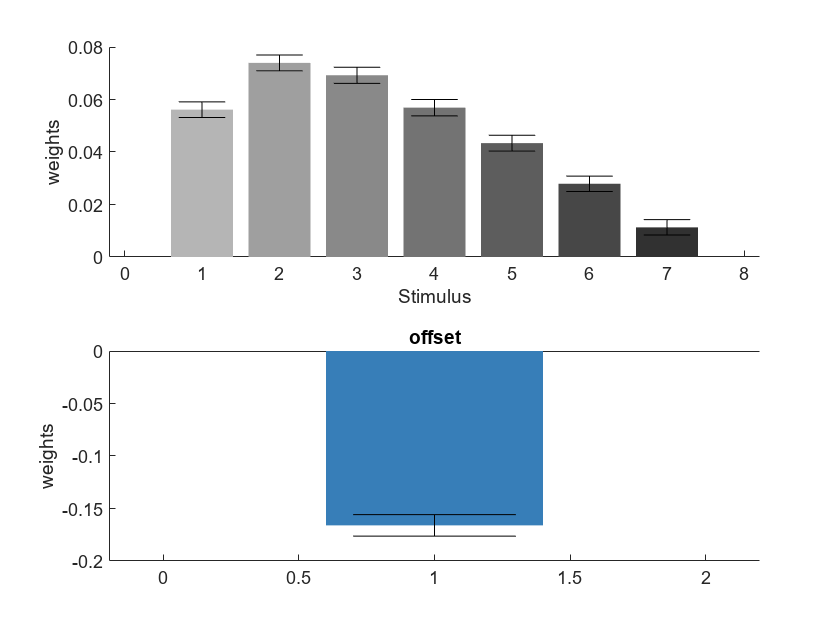

figure;
M.plot_weights;

We can then perform *model validation* (also known as *posterior predictive checks*) using `plot_data_vs_predictor` to check whether the model captures well the statistical dependencies between the stimulus and choice. We observe that although the data does follow the sigmoidal curve as expected, there are some systematic deviations that hint that some other factor may also condition behavior.

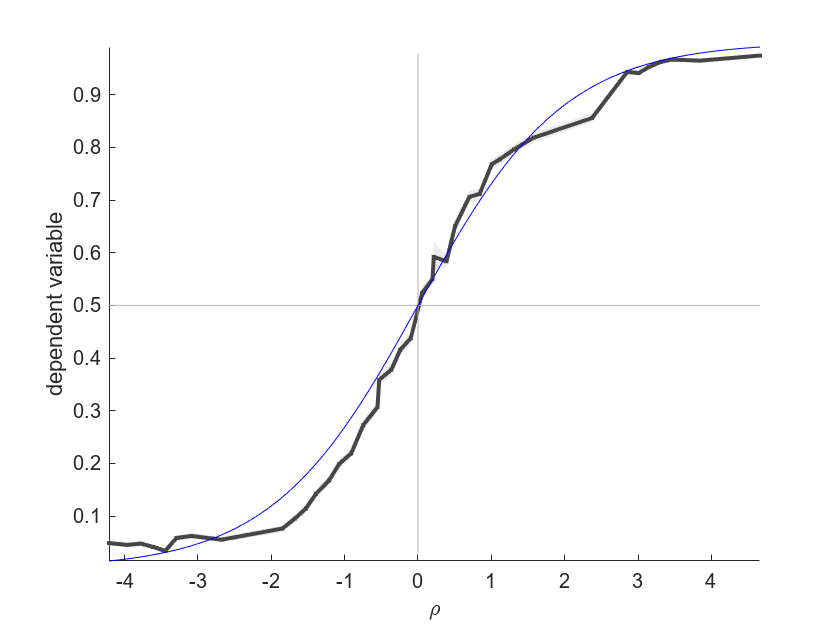

figure;
nQuantiles = 40; % we'll use 40 quantiles to compute the experimental psychometric cruve
M.plot_data_vs_predictor(nQuantiles);

For convenience we will rewrite this model using the variable '`Stimulus`' which stores the value of all seven motion pulses in each trial. This model is strictly equivalent to the previous one:

M = gum(T,'resp ~ Stimulus');

#### Splitted regressors

ADD TEXT

M = gum(T(T.session>106,:),'resp ~ Stimulus|session');
M.infer.plot_weights;

#### Lagged regressors

We can also *lagged regressors *and *splitted regressors. *Lagged regressors are used to capture the impact of regressors across trials (across observations when they represent a sequential process). Lagged regressors can be introduced by using the *lag() *operator in the GUM formula. For example the following model includes a regressor capturing the impact of the response on the previous trial, on trial *t-2 * and *t-3 * (i.e. lags=1,2, and 3). [Variable `response` is the response of the subject coded as -1/+1 for left/right].

M = gum(T,'resp ~ Stimulus + lag(response; lags=1:3)');

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29411.009041
Computing posterior covariance...done


Splitted regressors are simply regressors which are splitted based on the value of a categorical variable. Here suspect that the impact of the response on future responses will depend on whether that response was rewarded (i.e. correct) or not, so we split this regressor based on the value of `accuracy`*.*

M = gum(T,'resp ~ Stimulus + lag(response|accuracy; lags=1:3)');

ADD TEXT DESIGN MATRIX

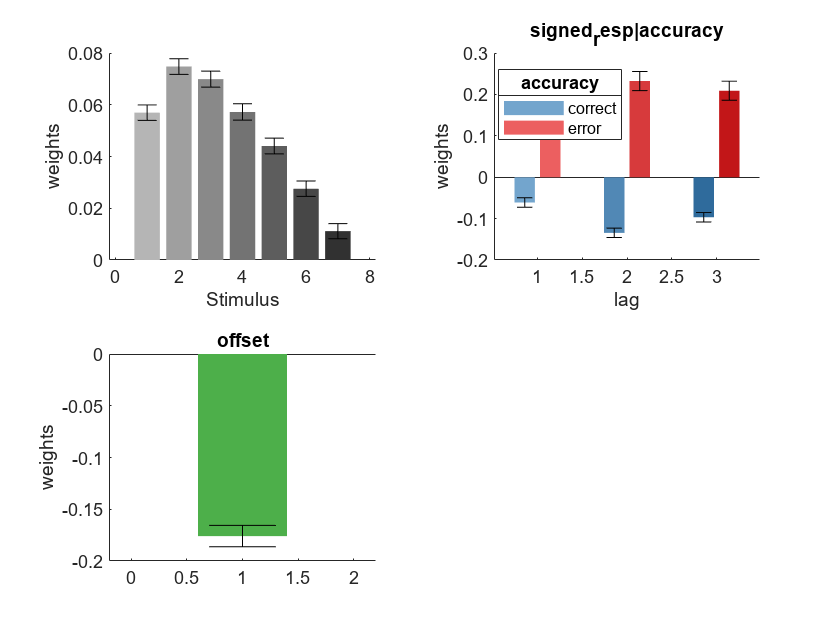

figure; 

M.plot_design_matrix(1:100)

ADD TEXT VIF

figure; M.plot_vif

The model weights are estimated and then plotted as seen previously. We see that previous choices do have an impact on the current choice: counter-intuitively, this animal is biased towards repeating a response (positive weights) if that response was associated with an error in any of the previous 3 trials, and against repeating (negative weights) if it was rewarded!

figure;

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -29480.002731
HP fitting: iter 2, log evidence -29460.837297
HP fitting: iter 3, log evidence -29460.324618
HP fitting: iter 4, log evidence -29460.042888
HP fitting: iter 5, log evidence -29459.798725
HP fitting: iter 6, log evidence -29459.560808
HP fitting: iter 7, log evidence -29459.323796
HP fitting: iter 8, log evidence -29459.086595
HP fitting: iter 9, log evidence -29458.848864
HP fitting: iter 10, log evidence -29458.610176
HP fitting: iter 11, log evidence -29458.370183
HP fitting: iter 12, log evidence -29458.128659
HP fitting: iter 13, log evidence -29457.885298
HP fitting: iter 14, log evidence -29457.717717
HP fitting: iter 15, log evidence -29457.550009
HP fitting: iter 16, log evidence -29457.381345
HP fitting: iter 17, log evidence -29457.211360
HP fitting: iter 18, log evidence -29457.040025
HP fitting: iter 19, log evidence -29456.867054
HP fitting: iter 20, log evidence -29456.692342
H

M = M.infer.plot_weights();

As a final note on GLMs: the default options is to include Gaussian priors on GLM weights. To understand how they work, how to set them or remove them, go to the full tutorial on GLMs.

### Generalized Additive Models

The toolbox allow to include the nonlinear impact of some regressors. For example, the data was collected from 112 different sessions, and the behavior of the animal may change from session to session. Notably, its bias towards rightward or leftward response may fluctuate slowly. We capture this using a GAM where we add nonlinear regressor as $f(session)$ which represents a nonlinear mapping of the session index. 

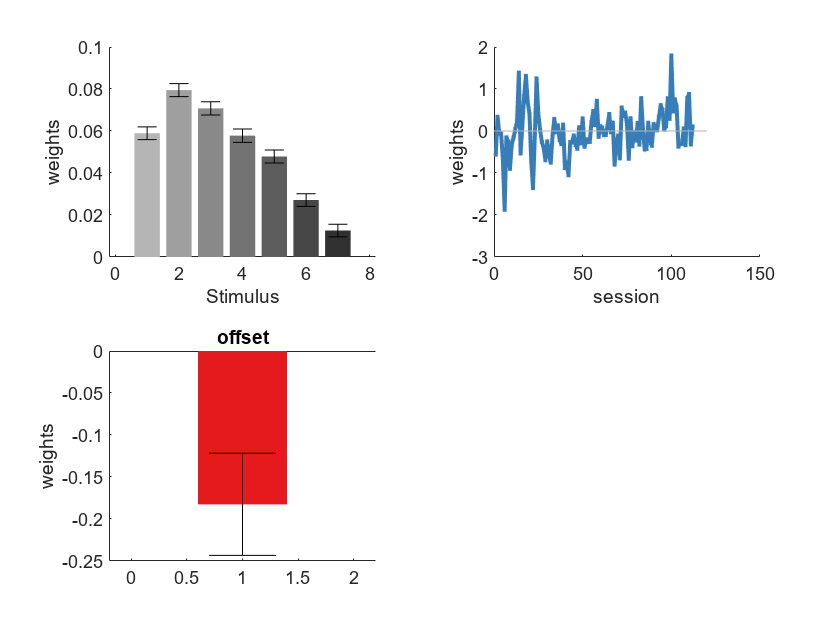

M = gum(T,'resp ~ Stimulus + f(session)');

The smoothness of the function (i.e. how fast it can change from session to session) depends on the prior which is set using Gaussian Processes (specifically a Squared Exponential prior). More concretely, there are two hyperparameters that control the variance and time scale of this prior. The value of weight estimates will depend on the value of these hyperparameters. Here we use the command `fit()` instead of `infer()` which allows to jointly estimate the weights (or rather the posterior distribution over the weights) and the hyperparameters. (Fitting this model can take a few minutes so please be patient or go get a coffee)

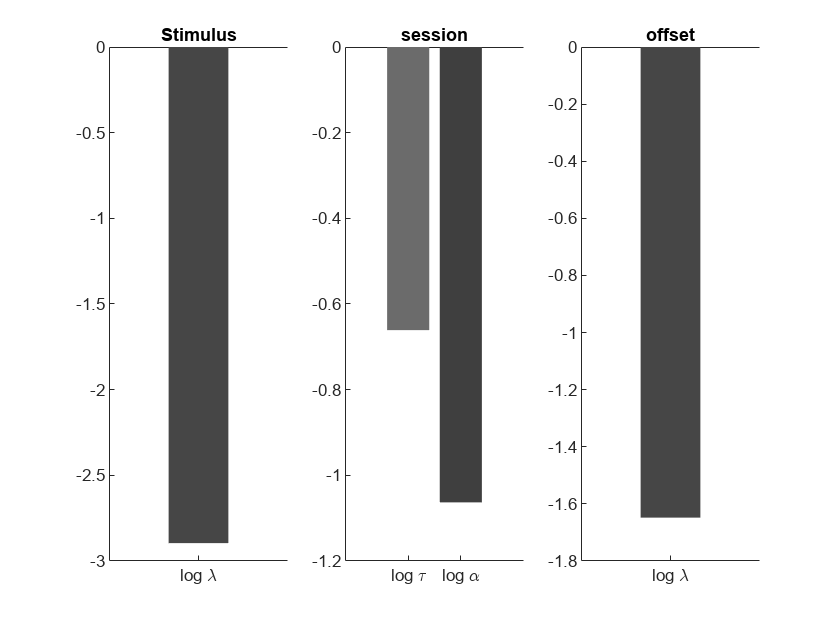

M = M.fit();
figure;

h = M.plot_weights;
figure; 
M.plot_hyperparameters;

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29569.898046
Computing posterior covariance...done


Another possibility for capturing the nonlinear mapping of regressors is to used a set of basis functions. For example we could capture the session-wise bias using a 5th order polynomial using the formula.

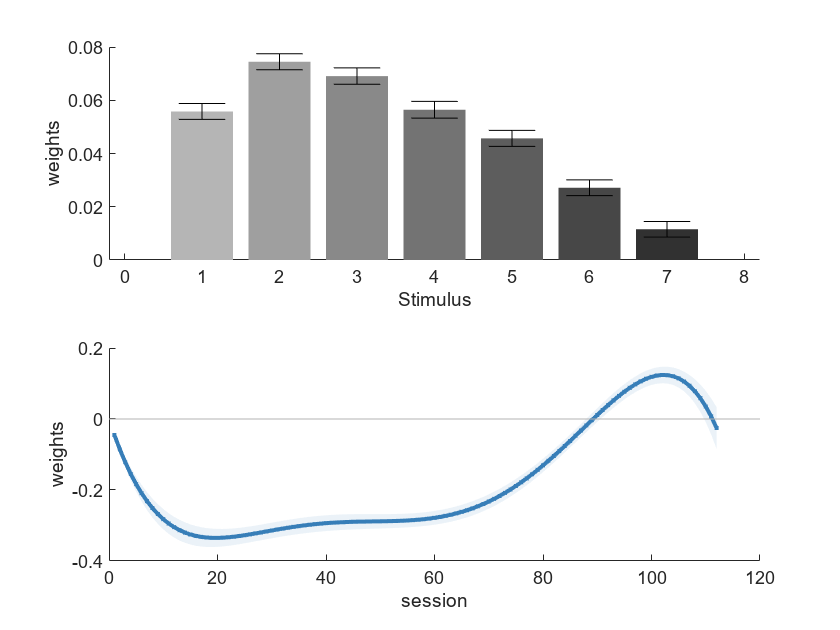

M = gum(T,'resp ~ Stimulus + poly5(session)');
M = M.infer();

figure; 
M.plot_weights;

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -29263.948549
HP fitting: iter 2, log evidence -29245.034387
HP fitting: iter 3, log evidence -29244.495237
HP fitting: iter 4, log evidence -29244.221079
HP fitting: iter 5, log evidence -29243.997690
HP fitting: iter 6, log evidence -29243.784457
HP fitting: iter 7, log evidence -29243.573680
HP fitting: iter 8, log evidence -29243.363667
HP fitting: iter 9, log evidence -29243.153883
HP fitting: iter 10, log evidence -29242.943934
HP fitting: iter 11, log evidence -29242.733693
HP fitting: iter 12, log evidence -29242.522802
HP fitting: iter 13, log evidence -29242.311193
HP fitting: iter 14, log evidence -29242.165810
HP fitting: iter 15, log evidence -29242.020699
HP fitting: iter 16, log evidence -29241.875251
HP fitting: iter 17, log evidence -29241.729039
HP fitting: iter 18, log evidence -29241.582094
HP fitting: iter 19, log evidence -29241.434158
HP fitting: iter 20, log evidence -29241.285150
H

As you can see, because the number of polynomial is fixed in the model, it does not allow for the same flexibility to adjust the smoothness to data as in Gaussian Processes (which is used when using the `f(session)` syntax). Basis functions can also be used for lagged regressors. Because the number of regressors scales with the number of lags, statistical power can prevent from including many lags into the model. This can be circumvented by assuming that the lags map onto a few exponential basis functions, i.e. weight at lag *l *follows $w_L = \sum_{k \leq 2} \exp(-l/ \tau_k)$. Here $\tau_k$ are hyperparmeters of the model which can be estimated using the `fit()` command.

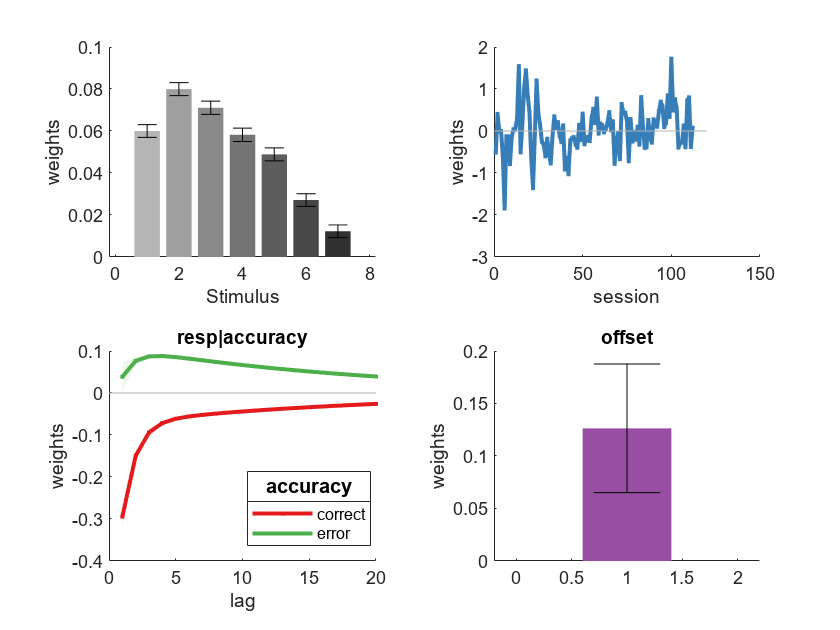

M = gum(T,'resp ~ Stimulus + f(session) + lag(resp|accuracy; lags=1:20; basis=exp2)').fit();
figure;

M.plot_weights;

Of course the two types of nonlinear mapping can be combined in a single formula, e.g. we could estimate the session-wise bias and history-dependent biases jointly using the following model:

M = gum(T,'resp ~ Stimulus + f(session) + lag(resp|accuracy; lags=1:20; basis=exp2)');

### Modelling over population

M = gum(T(T.session<=6,:),'resp|session ~ Stimulus + lag(resp|accuracy; lags=1:20; basis=exp2)');
fprintf("created " + length(M) + " models");

created 6 models

M = M.infer(struct('verbose','little'));

Inferring weights for model 1/6 ()
*

Inferring weights for model 2/6 ()
*

Inferring weights for model 3/6 ()
*

Inferring weights for model 4/6 ()
*

Inferring weights for model 5/6 ()
*

Inferring weights for model 6/6 ()
*




disp(M(1));

Generalized Unrestricted Model (GUM) object: unnamed model
resp|session ~ Stimulus + lag(resp|accuracy; lags=1:20; basis=exp2)
--------------------------------------------------------------------------------
            Type:            GAM         Observations:       binomial
 nRegressorBlock:            310     ObservationBlock:              3
   nObservations:            310          isEstimated:              1
        isFitted:              0              Dataset:       1.000000
     nParameters:             12      nFreeParameters:             12
              df:            298     nFreeHyperparameters:              5
         scaling:       1.000000     SplittingVariable:            NaN
   LogLikelihood:    -121.773955             LogPrior:      -0.543783
        LogJoint:    -122.317738             exitflag:              1
     LogEvidence:    -142.595163            BIC_infer:     312.386778
      

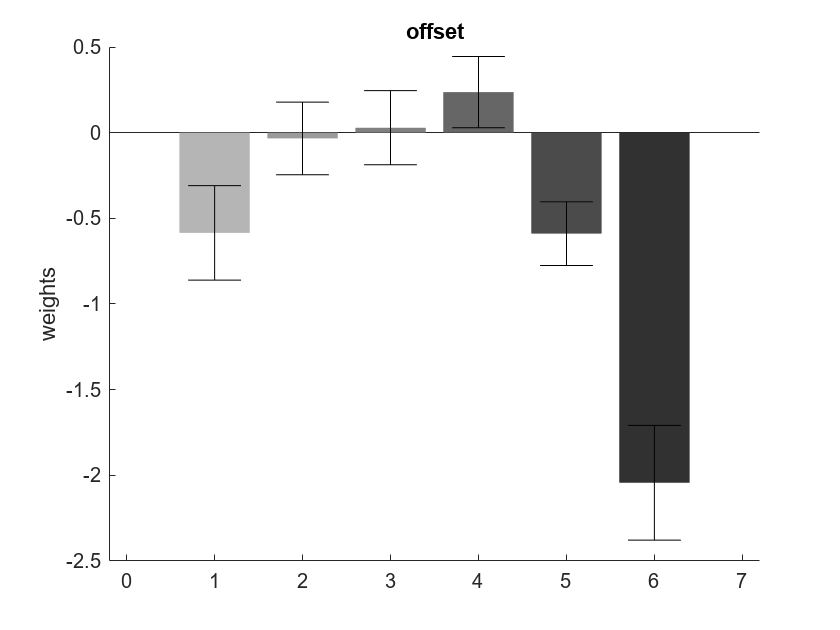


Mconc = M.concatenate_over_models;
figure;
Mconc.plot_weights();

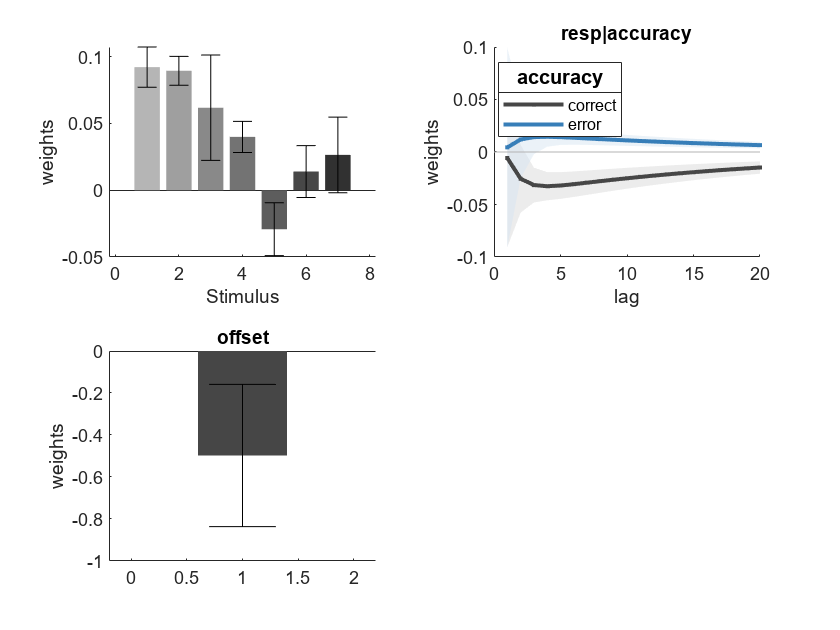


Mavg = M.population_average;
figure;
Mavg.plot_weights;

### Generalized Unrestricted Models (GUMs)

We now introduce 

M = gum(T,'resp ~ Stimulus*f(session) + cat(session) + lag(response|accuracy; Lags=1:10; split=false)');
M = M.infer;

Evaluating prior covariance matrix...done
Fitting weights, starting point 1/10
***>x>>
converged after 7 iterations, log-joint:-27598.927994
Fitting weights, starting point 2/10
****x***>o>
converged after 11 iterations, log-joint:-27598.927994
Fitting weights, starting point 3/10
****x*>>>o
converged after 10 iterations, log-joint:-27598.927994
Fitting weights, starting point 4/10
****x>>>>
converged after 9 iterations, log-joint:-27598.927994
Fitting weights, starting point 5/10
****x>>>
converged after 8 iterations, log-joint:-27598.927994
Fitting weights, starting point 6/10
****x>>>
converged after 8 iterations, log-joint:-27598.927994
Fitting weights, starting point 7/10
****x*>>>
converged after 9 iterations, log-joint:-27598.927994
Fitting weights, starting point 8/10
****x>>>
converged after 8 iterations, log-joint:-27598.927994
Fitting weights, starting point 9/10
****x*>>>o
converged after 10 iterations, log-joint:-27598.927994
Fitting weights, starting point 10/10
****x>>>>

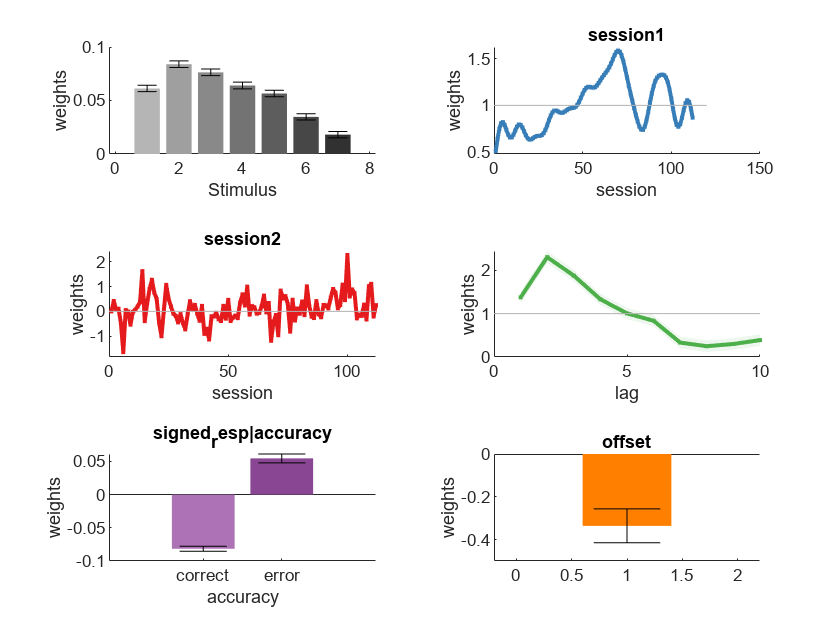

figure;
M.plot_weights;

M = gum(T,'resp ~ f(stimulus)*cat(session)');
M = M.infer;
M.plot_weights;

**Build model**

design matrix

[timeregressor]

**Inference & showing results**

GUM - loadfrom model

plot_weights (default, set_plot, disable_plot)

disp

**Posterior analyses**

metrics

model comparison (concatenate_reg), explained variance, predictor variance

validation: plot_data_vs_predictor, sampling from model

VIF, plot_posterior_covariance

**Lagged regressors**

**Hyperparameters**

Types of HPs: cov & basis

Setting value

Types of fitting

Plotting

**Second-level analysis**

define with y|subject ~

population average & plot

(relationship to mixed models)

**Manipulating data**

% -'extract_observations': extract model for only a subset of
    % observations
    % - 'isgam': whether model corresponds to a GAM
    % - 'isglm': whether model corresponds to a GLM
    % - 'isestimated': whether model weights have been estimated
    % - 'is_weight_set': whether model weights haven been assigned
    % - 'isfitted': whether hyperparameters have been fitted
    % - 'is_infinite_covariance': whether any regressor has infinite
    % covariance (i.e. no prior)
    % - 'number_of_regressors': number of regressors
    % - 'concatenate_weights': concatenates model weights into vector
    % - 'freeze_weights': freezes weights and parameters in the model
    % - 'knockout'
    % - 'clear_data'
    % - 'save': save model into .mat file
    % load_weights_from_model (and HPs)

Operations

 % - 'compute_rho_variance' provide the variance of predictor in output structure
    % - 'vif': Variance Inflation Factor
    % - 'sample_weights_from_prior': assign weight values sampling from
    % prior
    % - 'sample_weights_from_posterior': assign weight values sampling from
    % posterior
    % - 'Predictor': compute the predictor for each observation
    % - 'ExpectedValue': computes the expected value for each observation
    % - 'LogPrior': computes the LogPrior of the model
    % - 'LogLikelihood': computes the LogLikelihood of the model
    % - 'Accuracy': accuracy of the model predictions at MAP weights
    % - 'LogJoint': computes the Log-Joint of the model
    % - 'Hessian': computes the Hessian of the negative LogLihelihood
    % - 'PosteriorCov': computes the posterior covariance
    % - 'IRLS': core step in inference
    % - 'boostrapping': generate bootstrap estimates of weight uncertainty
    % - 'Sample': generate observations from model using MAP weights
    % - 'Sample_Observations_From_Posterior': generate observations from
    % model sampling from weight posterior
    % - 'ExplainedVariance': computes model explained variance
    % - 'predictor_variance': computes the variance of the predictors across
    % datapoints
    % - 'compute_rho_variance': computes variance of predictor for each
    % datapoint
    % - 'inverse_link_function': output inverse link function
